# Assignment 2

## 1 How finite should it be?

### 1.1 Like a hot knife through a Butterworth

Construct a bandpass filter which meets the following specifications (normalized frequency): 

- Passband from 0.2 to 0.3. 

- Stopbands from 0 to 0.1 and 0.4 to 1

- Ripples are OK if they don't exceed 2 dB

- The stopband attenuation should be at least -100 dB

clear all; clc;

% Filter specifications
Wp = [0.2 0.3]; % Passband corner frequencies
Ws = [0.1 0.4]; % Stopband corner frequencies
Rp = 2;         % Maximum ripple amplitude
Rs = -100;      % Stopband attenuation

% Butterworth bandpass filter design
[N_bw,Wn_bw] = buttord(Wp,Ws,Rp,-Rs); 
[B_bw,A_bw] = butter(N_bw,Wn_bw,"bandpass"); 

% Chebychev I bandpass filter design
[N_ch1,Wn_ch1] = cheb1ord(Wp,Ws,Rp,-Rs); 
[B_ch1,A_ch1] = cheby1(N_ch1,Rp,Wn_ch1,"bandpass"); 

% Chebychev II bandpass filter design
[N_ch2,Wn_ch2] = cheb1ord(Wp,Ws,Rp,Rs); 
[B_ch2,A_ch2] = cheby2(N_ch2,-Rs,Wn_ch2,"bandpass"); 

% Elliptical bandpass filter design
[N_ep,Wn_ep] = ellipord(Wp,Ws,Rp,-Rs);
[B_ep,A_ep] = ellip(N_ep,Rp,-Rs,Wn_ep,"bandpass"); 

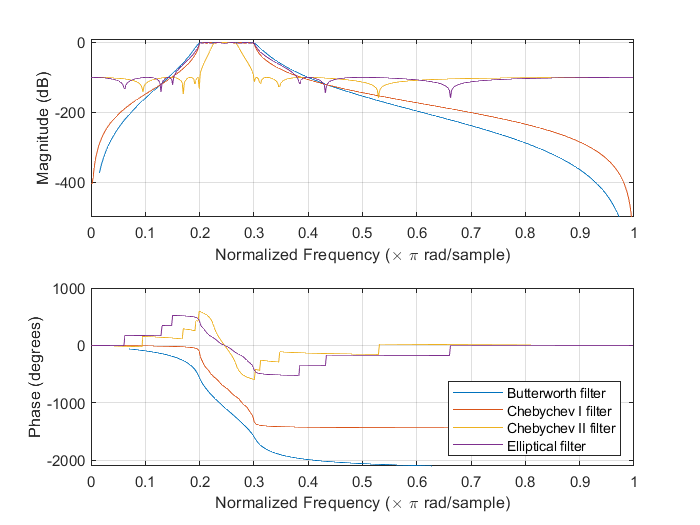

% Frequency responses of four different filters with same specifications
figure("Name", "FR")
subplot(2,1,1)
[H_bw,W] = freqz(B_bw,A_bw); 
[H_ch1,~] = freqz(B_ch1,A_ch1); 
[H_ch2,~] = freqz(B_ch2,A_ch2);
[H_ep,~] = freqz(B_ep,A_ep);
plot(W/pi,20*log10(abs(H_bw))), hold on;
plot(W/pi,20*log10(abs(H_ch1))), hold on;
plot(W/pi,20*log10(abs(H_ch2))), hold on;
plot(W/pi,20*log10(abs(H_ep))), hold off
grid on
ylim([-500 10])
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Magnitude (dB)")
subplot(2,1,2)
[phi_bw,~] = phasez(B_bw,A_bw);
[phi_ch1,~] = phasez(B_ch1,A_ch1);
[phi_ch2,~] = phasez(B_ch2,A_ch2);
[phi_ep,~] = phasez(B_ep,A_ep);
plot(W/pi,phi_bw*180/pi), hold on;
plot(W/pi,phi_ch1*180/pi), hold on;
plot(W/pi,phi_ch2*180/pi), hold on;
plot(W/pi,phi_ep*180/pi), hold off
grid on
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Phase (degrees)")
legend(["Butterworth filter","Chebychev I filter","Chebychev II filter","Elliptical filter"],"Location","southeast")
saveas(gcf,"plots/filter_types_freq_resp","png");

In the following, we choose to pursue the Butterworth filter design, as it provides a flat passband gain with sufficient stopband attenuation. 

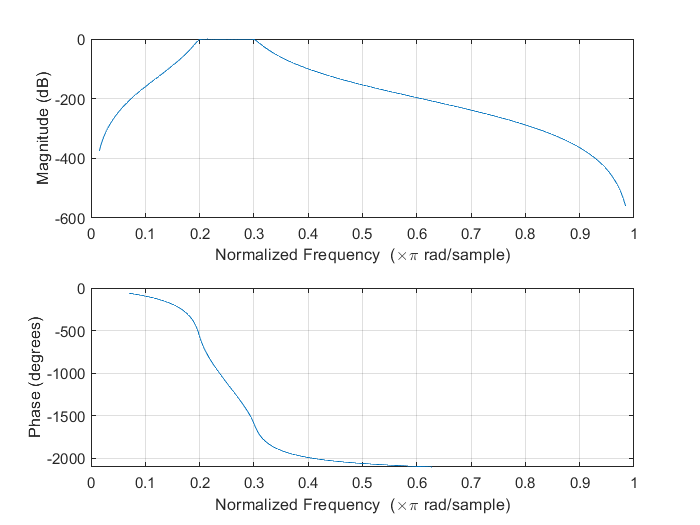

% Frequency response
freqz(B_bw,A_bw); disp(Wn_bw)

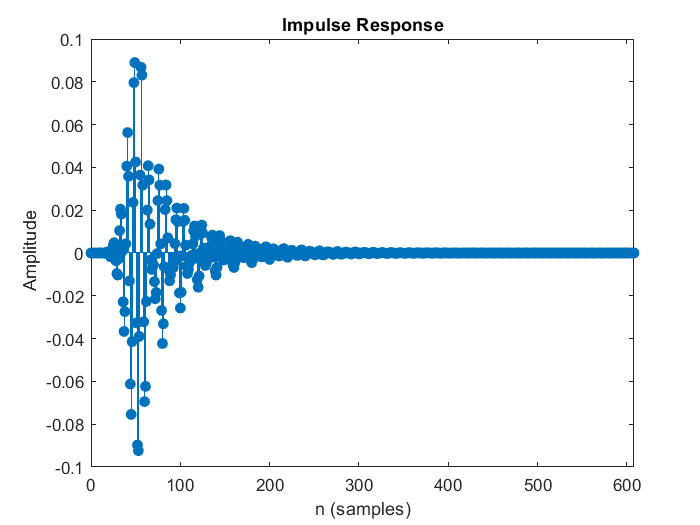

% Impulse response
impz(B_bw,A_bw); 

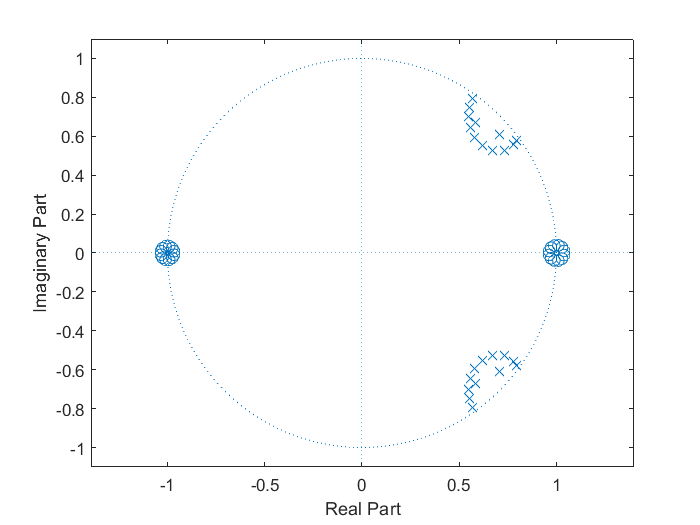

% z-plane plot
zplane(B_bw,A_bw)

Now take the impulse response. Let’s define for practical reasons an effective length of the impulse response the length (in samples) at which the impulse response decays below a value of 10% of its maximum. Now vary the length of the filter:

- Cut the filter at its effective length

- Cut the filter to 75%/60%/40%/10% of its effective length

and compare the frequency response of the resulting filters by plotting them on top of each other. Use a rectangular window and one other window of your choice. Describe what happens to the frequency response when the impulse responses are shortened. 

% Get the impulse response of the Butterworth filter
[h,t] = impz(B_bw,A_bw);

% Find the effective length of the impulse response, where h > 10% of max(H)
el = find(h > 0.1*max(h), 1, "last");

% Cut the filter to 100%/75%/60%/40%/10% of its effective length
h_el = h(1:el);
h_75el = h(1:fix(0.75*el));
h_60el = h(1:fix(0.60*el));
h_40el = h(1:fix(0.40*el));
h_10el = h(1:fix(0.10*el));

% Fourier transform the impulse response to get the filters' frequency response 
H_el = fft(h_el); H_el = H_el(1:ceil(length(H_el)/2));
H_75el = fft(h_75el); H_75el = H_75el(1:ceil(length(H_75el)/2)); 
H_60el = fft(h_60el); H_60el = H_60el(1:ceil(length(H_60el)/2));
H_40el = fft(h_40el); H_40el = H_40el(1:ceil(length(H_40el)/2));
H_10el = fft(h_10el); H_10el = H_10el(1:ceil(length(H_10el)/2));

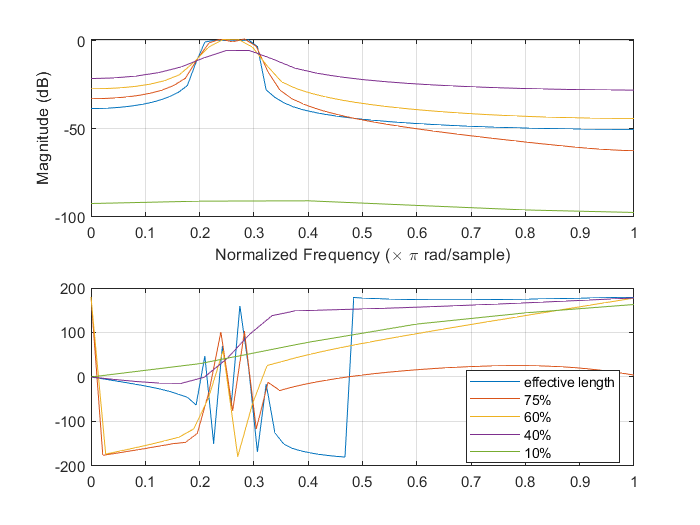

% Plot the frequency responses at different filter lengths
figure("Name", "Frequency response at different effective lengths")
subplot(2,1,1)
plot(linspace(0,1,length(H_el)), 20*log10(abs(H_el))), hold on;
plot(linspace(0,1,length(H_75el)), 20*log10(abs(H_75el))), hold on;
plot(linspace(0,1,length(H_60el)), 20*log10(abs(H_60el))), hold on;
plot(linspace(0,1,length(H_40el)), 20*log10(abs(H_40el))), hold on;
plot(linspace(0,1,length(H_10el)), 20*log10(abs(H_10el))), hold off
grid on
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Magnitude (dB)")
subplot(2,1,2)
plot(linspace(0,1,length(H_el)), rad2deg(angle(H_el))), hold on;
plot(linspace(0,1,length(H_75el)), rad2deg(angle(H_75el))), hold on;
plot(linspace(0,1,length(H_60el)), rad2deg(angle(H_60el))), hold on;
plot(linspace(0,1,length(H_40el)), rad2deg(angle(H_40el))), hold on;
plot(linspace(0,1,length(H_10el)), rad2deg(angle(H_10el))), hold off
grid on
legend(["effective length", "75%", "60%", "40%", "10%"],"Location", "best");
saveas(gcf,"plots/eff_length_freq_resp","png"); 

### 1.2 Shorter and shorter

For an application you are to construct a FIR lowpass filter by the frequency domain equivalence, i.e. by sampling the frequency response of a perfect lowpass filter. You got a sheet of paper from you colleague that holds the specs: The filter passes all frequencies between 0 and 5 kHz with a gain af 0 dB. Just over the sampling frequency, there is this huge coffee stain, making it impossible to read, the same for the order of the desired filter. But you see from the sketch that the cutoff of the filter corresponds to one third on a normalized frequency axis, and you can see that the impulse response should be 601 samples long. 

- Which sampling rate should you use? 

- Construct the filter and plot the frequency and the impulse response

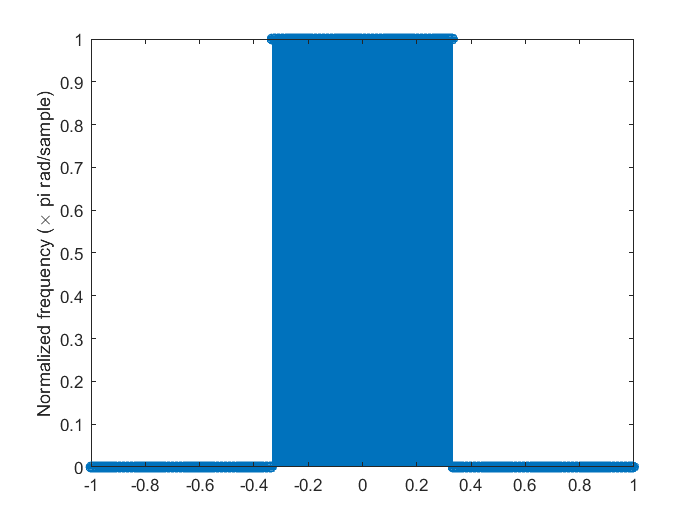

fs = 3e4;   % Sampling frequency
fn = fs/2;  % Nyquist frequency
T = 601/fs; % Duration of impulse response
FR = [ones(1,fn/3) zeros(1,2*fn/3)]; 
FR = [flip(FR) FR(2:end)]; 
figure("Name", "FR plot")
stem(linspace(-1,1,length(FR)),FR)
ylabel("Normalized frequency (\times pi rad/sample)")

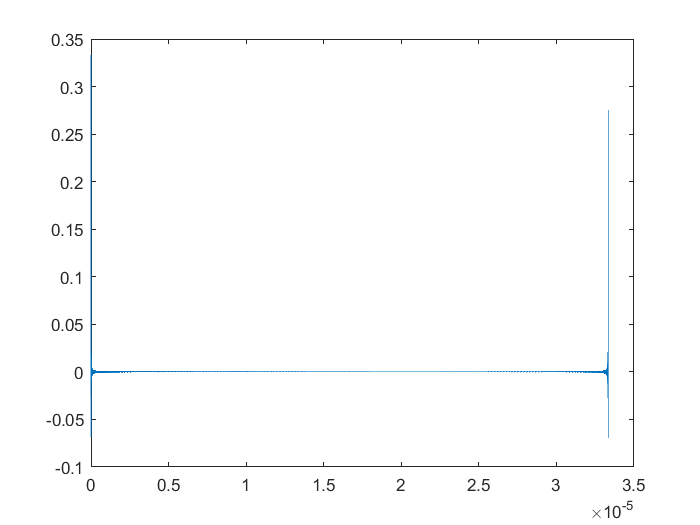

IR = ifft(ifftshift(FR)); 
t = linspace(0,1,numel(IR))/fs;
figure("Name", "IR plot")
plot(t,IR)

## 2 An equalizer - without buttons

### 2.1 Bass and treble

function [b,a] = fir_bandpass_filter(w_c1,w_c2,G,L)

end